clc
clear

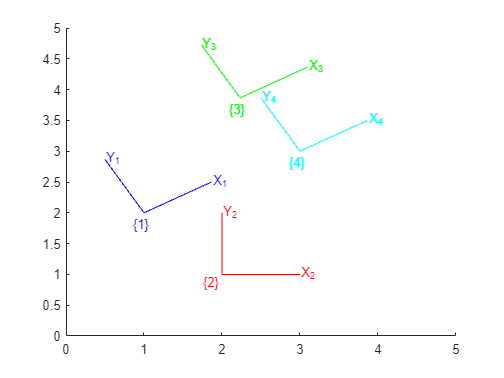

% Page 22 of textbook. se2 function was replaced with SE2 class. See the
% page 224 of the documentation.
% 
% Matlab contains a built in se2 function.

T1 = SE2(1, 2, deg2rad(30));
T2 = SE2(2, 1, deg2rad(0));
T3 = T1 * T2;
T4 = T2 * T1;
axis([0 5 0 5])

% Using hold on/hold off to plot multiple graphs in one figure
hold on
trplot2(T1, 'frame', '1', 'color', 'b')
trplot2(T2, 'frame', '2', 'color', 'r')
trplot2(T3, 'frame', '3', 'color', 'g')
trplot2(T4, 'frame', '4', 'color', 'c')
hold off

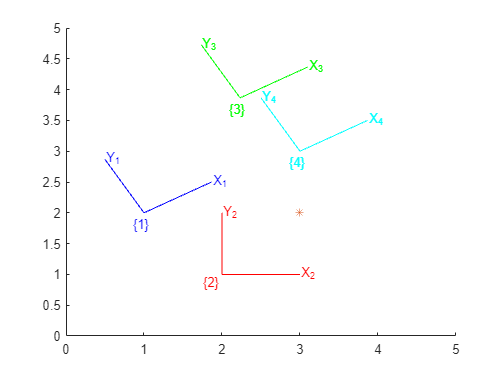

P = [3; 2];
plot_point(P, '*')



% This code does not work
%P1 = inv(T1) * [P; 1]

% This code works. Since T1 is an object of a class now I have to use
% .double function to get a matrix. Matlab shows a warning for using inv()
% function and suggests to replace it with matrix division.
% P1 = inv(T1.double) * [P; 1]

% The correct line
P1 =  T1.double \ [P; 1]

P1 =     1.7321
   -1.0000
    1.0000



h2e(T1.double \ e2h(P))

ans =     1.7321
   -1.0000



P2 = homtrans(inv(T2.double), P)

P2 =      1
     1
